clear all
close all
clc

rng(1);

load('wiener/WH_TestDataset')
testData = dataMeas;

% load('wiener/WH_SineInput_meas')
load('wiener/WH_EstimationExample')

% load('wiener/WH_CombinedZeroMultisineSinesweep')


trainData = dataMeas;
% uEst=smoothdata(uEst,'gaussian',2);
% yEst=smoothdata(yEst,'gaussian',2);


% plot(trainData.u(1:20000,1))
% plot(trainData.y(1:20000,1))
% 
% plot(testData.r(:,1))
% plot(testData.y)

Preprocessing Data

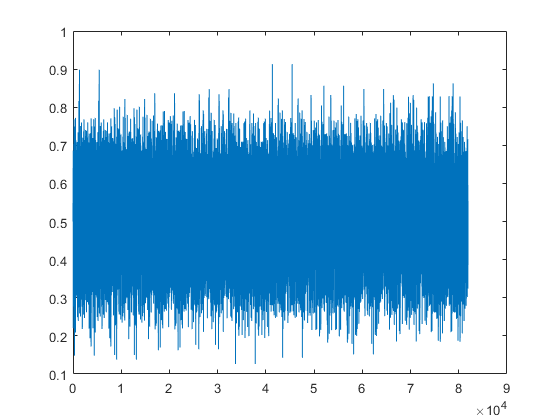

tic

% input = [trainData.u(1:20000,1)/8+0.5  ; trainData.u(1:20000,2)/8+0.5];
% output = [trainData.y(1:20000,1)/0.8+0.5;trainData.y(1:20000,2)/0.8+0.5];

input = trainData.u(:)/8+0.5;
output = trainData.y(:)/0.8+0.5;


% input = trainData.u(:,1)/12+0.5;
% output = trainData.y(:,1)/1.2+0.5;


input(input<0)=0;
output(output>1)=1;

% parcorr(input,100)
% parcorr(output,100)
plot(input)

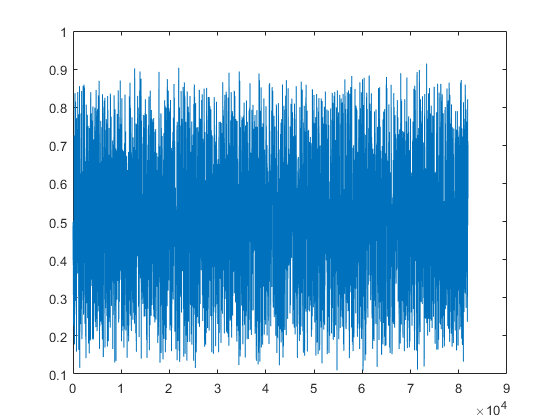

plot(output)


% histogram(input)
% histogram(output)

tinput = testData.u(:,1)/8+0.5;
toutput = testData.y(:,1)/0.8+0.5;

% tinput = [trainData.u(:,1)/8+0.5  ; trainData.u(:,2)/8+0.5];
% toutput = [trainData.y(:,1)/0.8+0.5;trainData.y(:,2)/0.8+0.5];

trainsize = size(output,1)-300;
testsize =  size(toutput,1)-300;

% Choose the lags for the input
% inlags=[1 2 3 4 5 8];
inlags=[1 8]

inlags =      1     8


for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-trainsize:end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-testsize:end-inlags(l));
end

% Choose the lags for the output, 0 is the estimated output
% outlags=[0 1 2 3 4 5 6 7 8];
outlags=[0 1 2 4 8 16 32];
outlags=[0 1 8]

outlags =      0     1     8



for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-trainsize:end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-testsize:end-outlags(l));
end



Split test and training set

featurez = [y(:,2:end)  u];
zeta = y(:,1);

tfeaturez = [yv(:,2:end)  uv];
yt = yv(:,1);


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                  %degree B-spline
m = 3;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 6;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 0.38889



rez = [];

Optimize TT cores

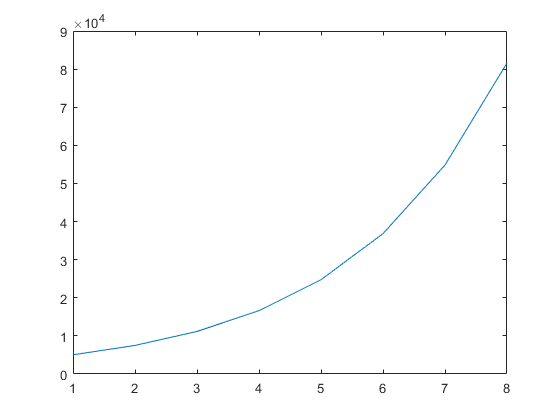

lambda=1*10^-7 ;
gamma=0;

difforder=2;
MAXITR = 2*d;


nselect = floor(logspace(log10(10*dof/N),0,MAXITR)*N);
plot(nselect)


% MAXITR = d;
% nselect = ones([1,MAXITR])*N;


[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);

    "iteration:"    "1"    "0.09162"

    "iteration:"    "2"    "0.19271"

    "iteration:"    "3"    "0.40421"

    "iteration:"    "4"    "0.5461"

    "iteration:"    "5"    "0.72596"

    "iteration:"    "6"    "0.9269"

    "iteration:"    "7"    "1.2028"

    "iteration:"    "8"    "1.5555"



rez = [rez res1];

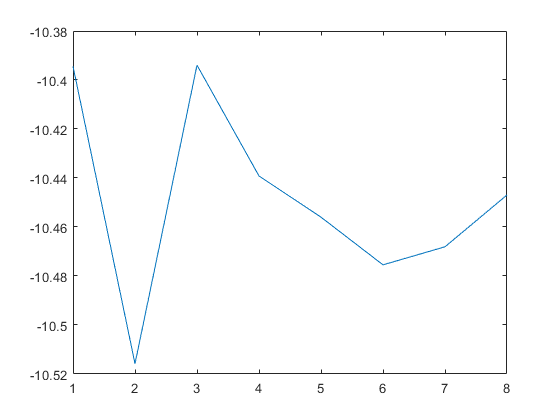


plot(log(res1))

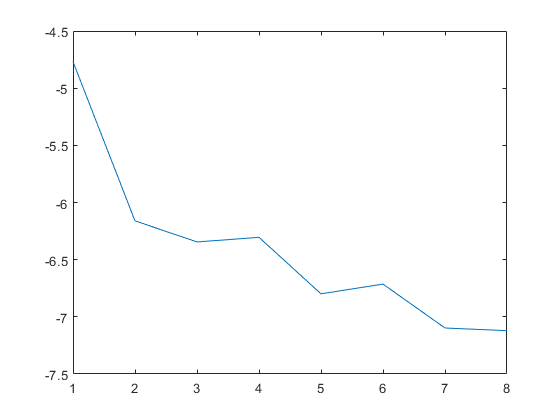

plot(log(res2))


trainerror = res1(end);

% plot(rez)

Evaluate Train data

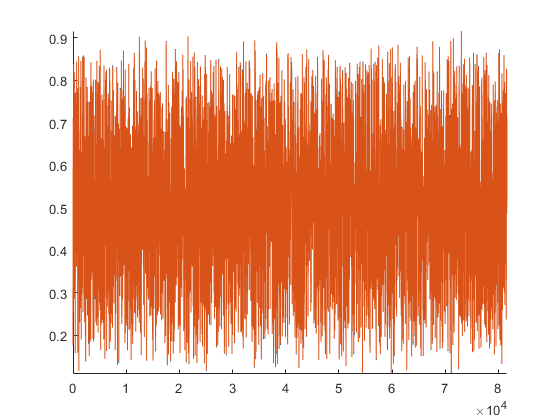


yhattrain  = evalspline(TN,featurez,n,m);

figure;
hold on
plot(zeta)
plot(yhattrain)
hold off
axis([0 inf -inf inf]);


erboiz = (yhattrain-zeta);
VAF = 1-var(erboiz)/var(zeta)

VAF = 0.9990

MSE = immse(yhattrain,zeta)

MSE = 2.9038e-05

Evaluate Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = 0.9994

MSE = immse(yhat,yt)

MSE = 1.4225e-05



RMSE = sqrt(immse(0.8*yhat,0.8*yt))

RMSE = 0.0030

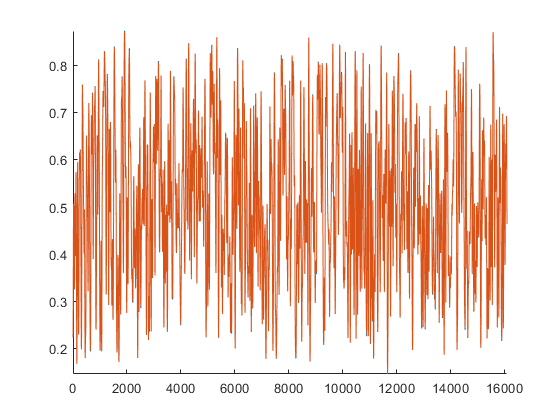


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

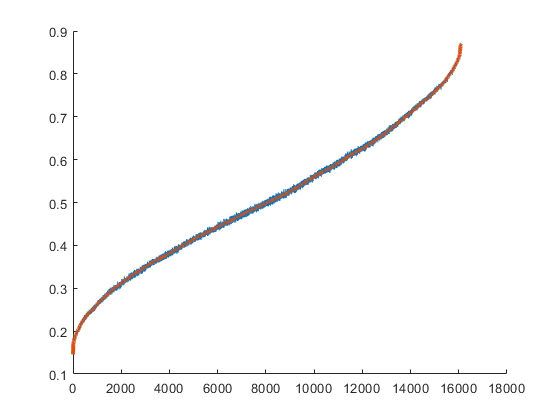


%  Visualize errors
[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off


% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off


% plot(tinput)
% plot(toutput)

siminput = tinput;
simoutput = toutput;
numz = numel(outlags);
for j = outlags(end)+inlags(end)+1:length(simoutput)
simfeaturez = [simoutput(j-outlags(2:end))' siminput(j-inlags(1:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

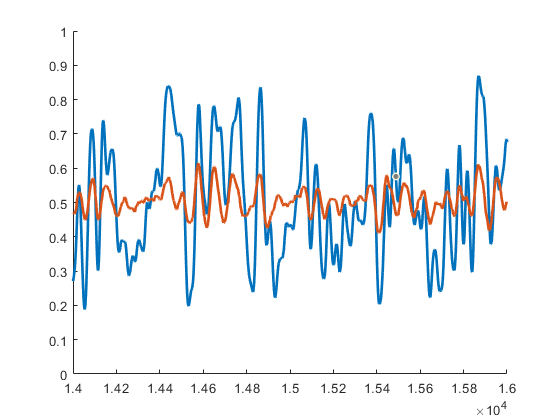


figure
hold on
plot(toutput(1:length(simoutput)),'linewidth',2)
plot(simoutput(1:length(simoutput)),'linewidth',2)
hold off
axis([14000 16000 0 1])

RMSE = sqrt(immse(0.8*toutput,0.8*simoutput))

RMSE = 0.1084

% simfeaturez = tfeaturez;
% simfeaturez(boolean(eye(9)))
% 
% diag(ones(1,5),-1)
% 
% ones(5,2)
toc

Elapsed time is 5.513837 seconds.
